# Common Data Visualizations

## Bar graph

y = [75 91 105 123.5 131 150 179 203 226 249 281.5];
bar(y)
% With a single input - Matlab will infer x axis as order and number of elements


% Can include x axis information
x = 1900:10:2000;
bar(x,y)


% Grouped - input a matrix - group id encoded by column number - observations by x
close all
y = [2 2 3; 2 5 6; 2 8 9; 2 11 12]
bar(y)


% Stacked
close all
y = [2 2 3; 2 5 6; 2 8 9; 2 11 12];
bar(y,'stacked')

% Change bar color with property variables
close all
b = bar(rand(10,1));
b.FaceColor = 'flat';
b.CData(2,:) = [.5 0 .5];

% Requires RGB vector
b.CData(4,:) = 'r'; 

b.CData(4,:) = [1 0 0]; 

## Add Error bars

clear; close all
data = rand(10,1); % Create some data
b = bar(data); % Plot the bar graph
hold on % Hold on for error lines


err = rand(10,1) - 0.5; % Create the error bar information (usually a measure of variation)
e1 = errorbar(data, err); % Create handle for error plot components 

e1.LineStyle = 'none'; % Remove adjoining lines
e1.Color = 'k';

## Scatterplot

clear; close all
x = linspace(0,3*pi,200);
y = cos(x) + rand(1,200);
plot(x,y,'o') % could acomplish with plot()

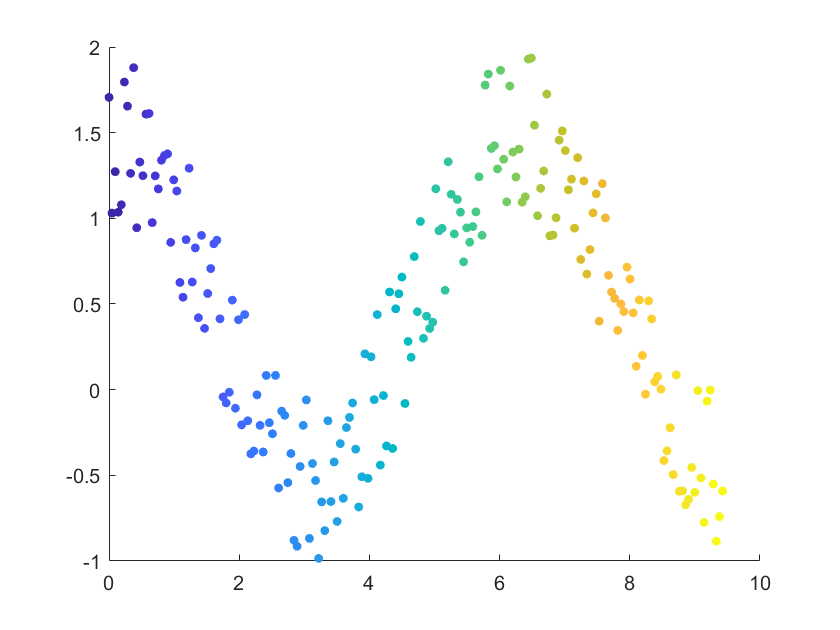

% Add size and color easily
sz = linspace(1,100,200);
c = linspace(1,100,length(x));
scatter(x,y,20,c,'filled') 

% Inspect size and color inputs
size(c)
histogram(c)

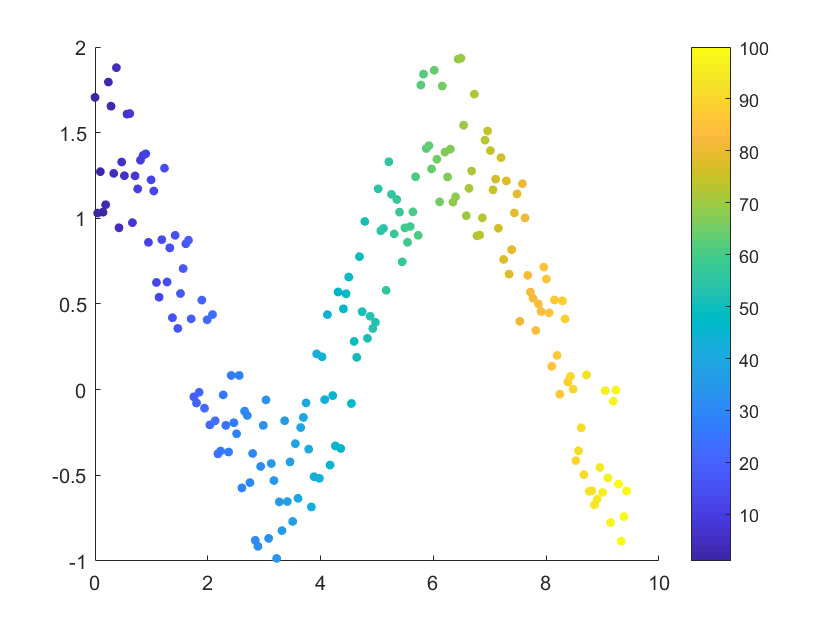

colorbar;colormapeditor

% Single color
c = [1 0 0]

c =      1     0     0


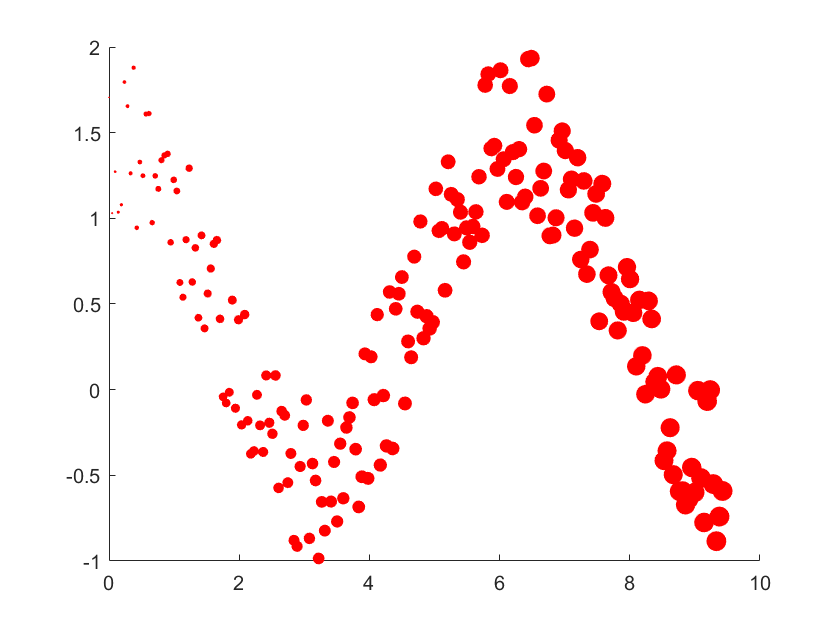

scatter(x,y,sz,c,'filled') 

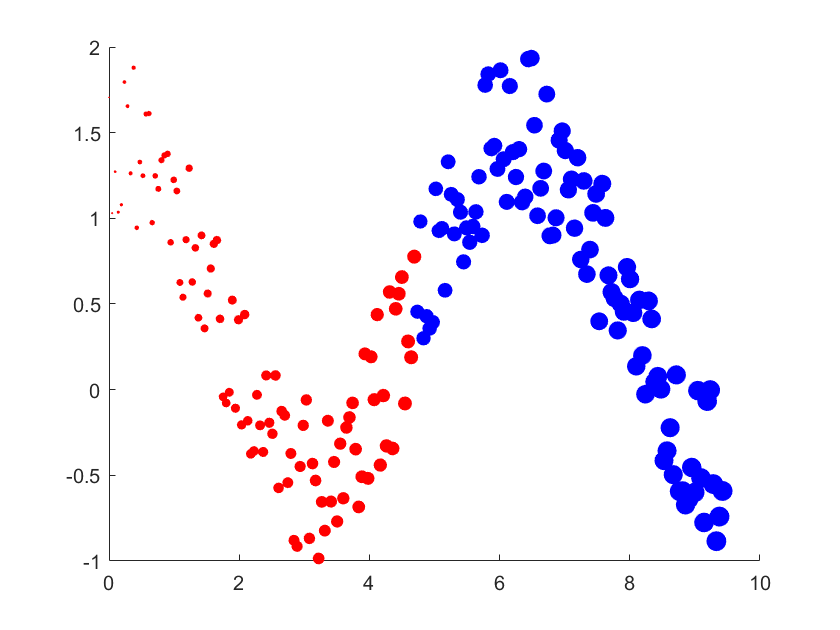

% 2 Colors
c = [repmat([1 0 0],100,1) ; repmat([0 0 1],100,1)];
scatter(x,y,sz,c,'filled') 

## Histogram

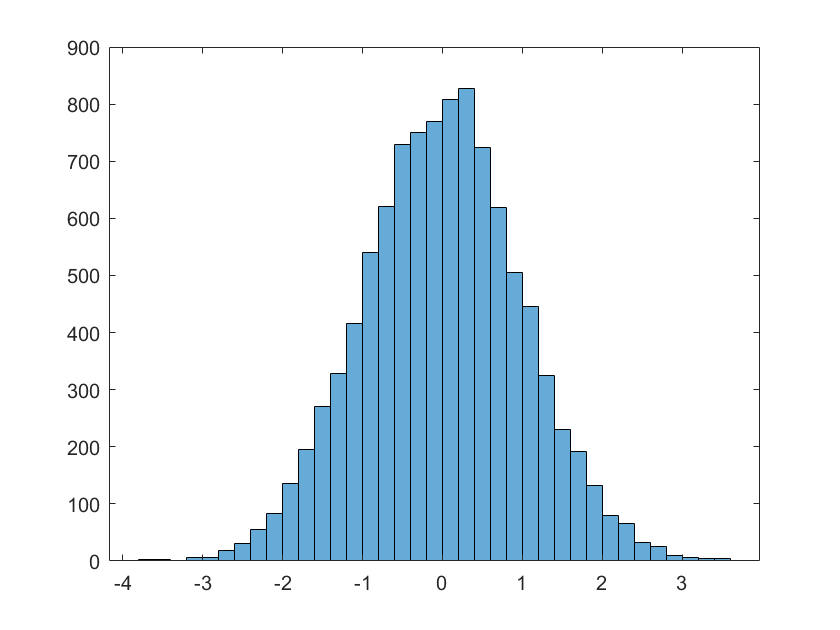

% Normal
x = randn(10000,1);
histogram(x);

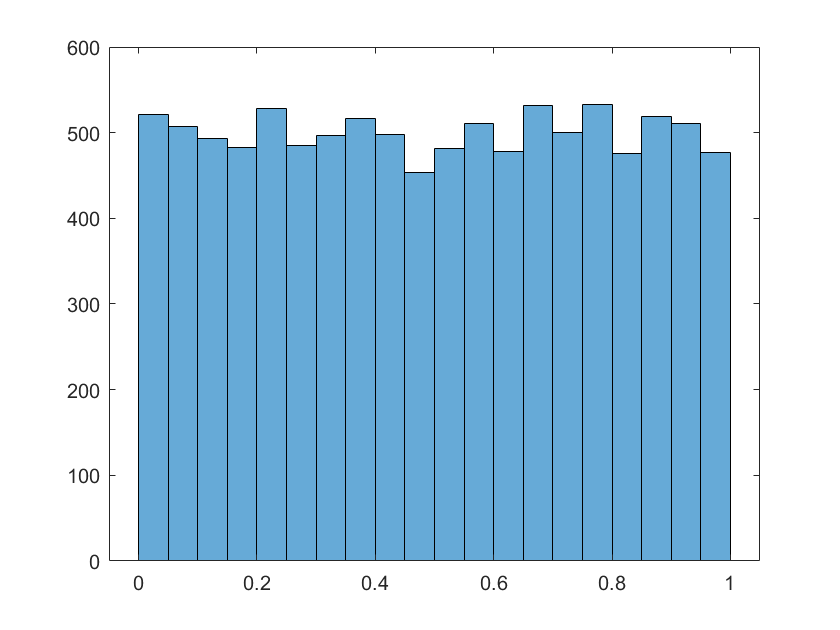

% Uniform
x2 = rand(10000,1);
h2 = histogram(x2);

ans = 22

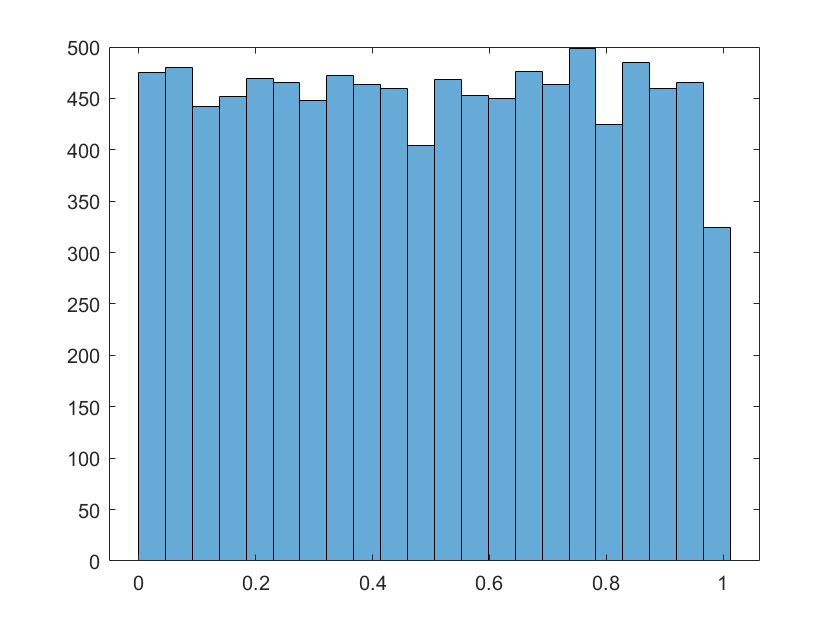

morebins(h2)

ans = 25

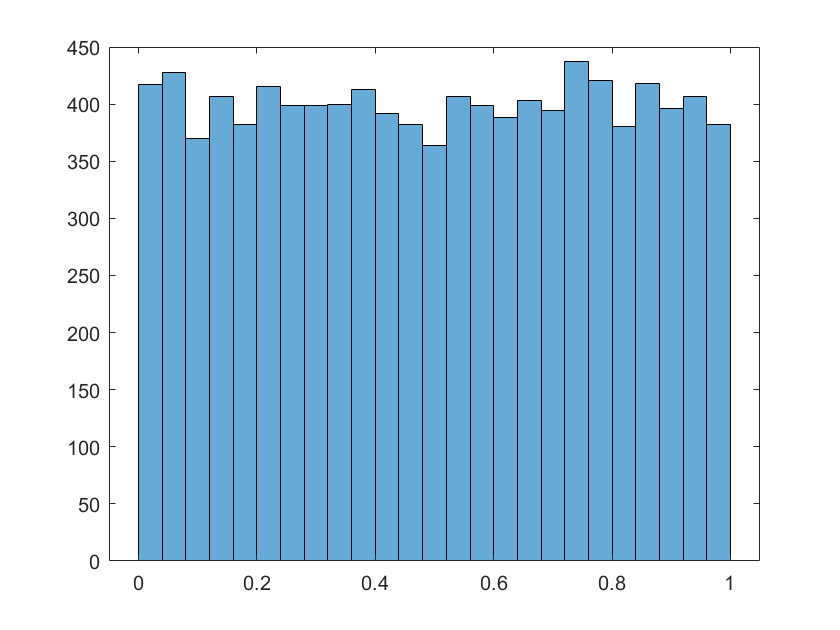

morebins(h2)

ans = 28

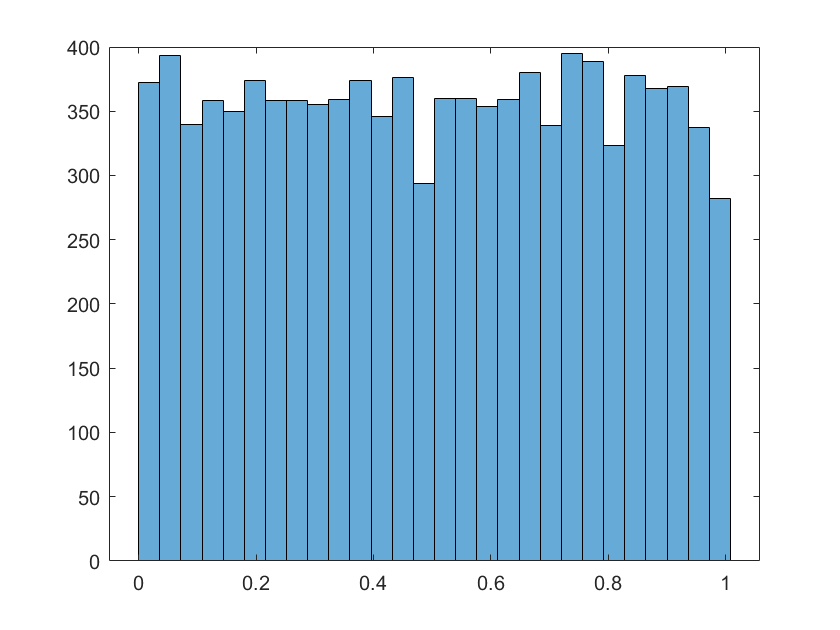

morebins(h2)

h2 =   Histogram with properties:

             Data: [10000×1 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.0100
        BinLimits: [0 1]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


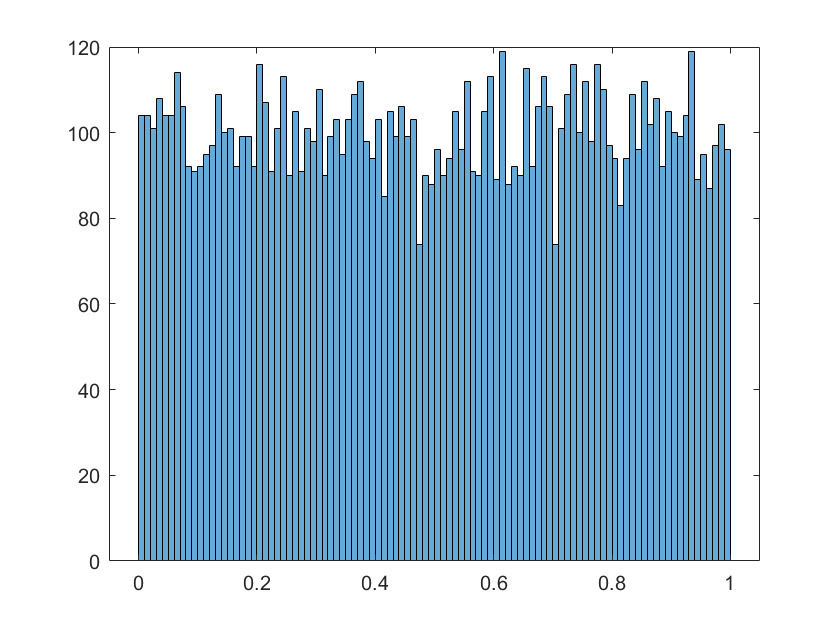

h2.NumBins = 100

## Normalization

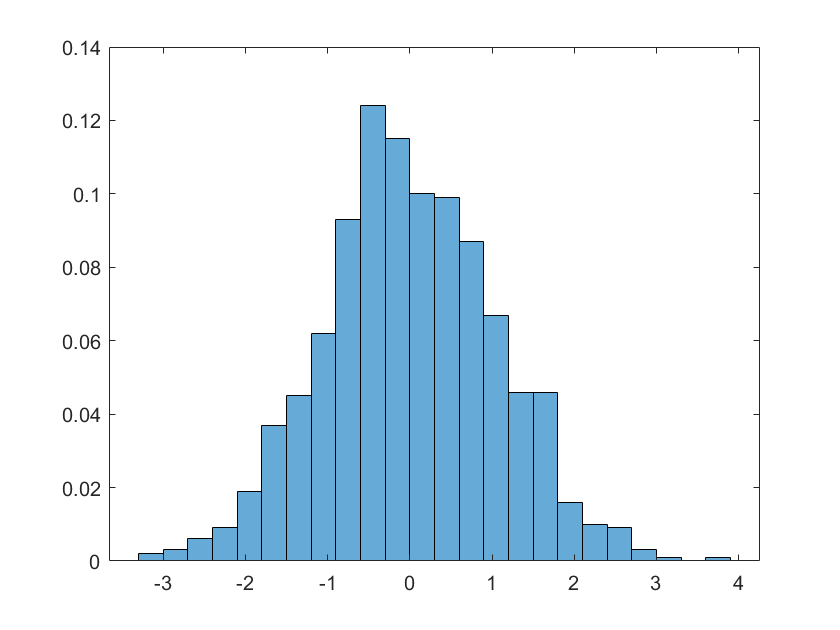

x = randn(1000,1);
h = histogram(x,'Normalization','probability');

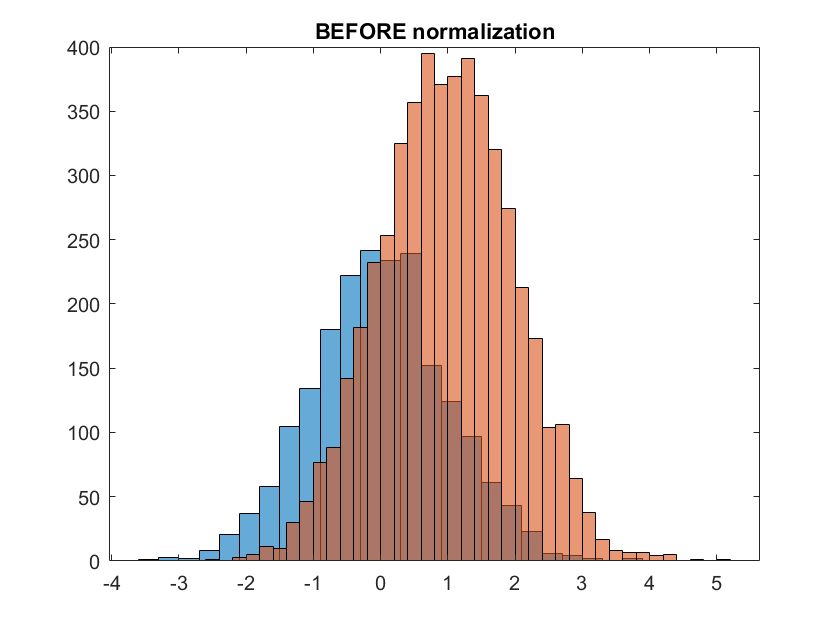

clear;close all
figure;
x = randn(2000,1);
y = 1 + randn(5000,1);
h1 = histogram(x);
hold on
h2 = histogram(y);
title('BEFORE normalization')

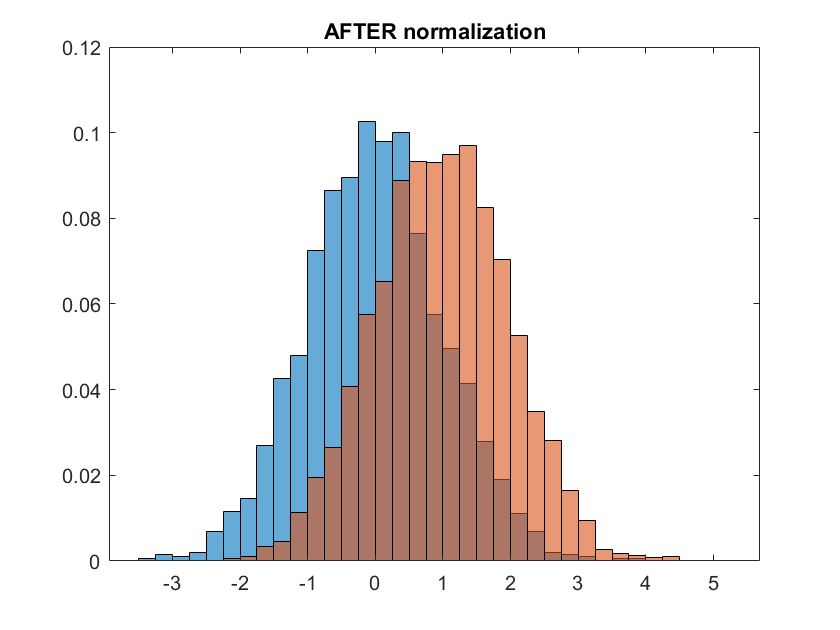

h1.Normalization = 'probability';
h1.BinWidth = 0.25;
h2.Normalization = 'probability';
h2.BinWidth = 0.25;
title('AFTER normalization')

## Boxplot

load carsmall
MPG

MPG =     18
    15
    18
    16
    17
    15
    14
    14
    14
    15


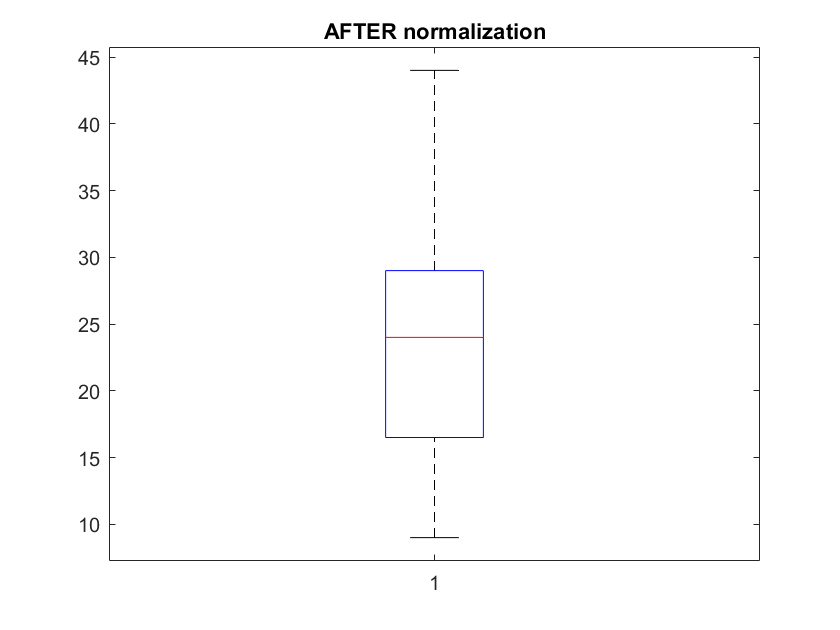

boxplot(MPG)

## Practice

% Load the dataset
load fisheriris.mat
dataset = meas;
var1 = dataset(:,1);
var2 = dataset(:,4);

usp = unique(species);
flowerIDs = zeros(size(species));
for ui = 1:length(usp)
    index = ismember(species,usp{ui});
    flowerIDs(index) = ui;
end

% VAR 1 = Sepal Length
% VAR 2 = Petal Width
% FLOWERIDS = Flower identity

## Create a Scatterplot of VAR1 vs VAR2 where each Flower is assigned a different color

%%% YOUR CODE
% Flower 1
scatter(var1(flowerIDs == 1),var2(flowerIDs == 1),20,'r')
hold on
% Flower 2

% Flower 3



## Create 2 separate barplots (one for each variable) representing the means of the 3 Flowers - make the bars red for both

%%% YOUR CODE
% Calculate means for flowers in variable 1 and variable 2
close all

v1mean = zeros(1,3);
v2mean = zeros(1,3);
v1std = zeros(1,3);
v2std = zeros(1,3);

for i = 1:3
    v1mean(i) = mean(var1(flowerIDs == i))
    v2mean(i) = mean(var2(flowerIDs == i))
    
    v1std(i) = std(var1(flowerIDs == i))
    v2std(i) = std(var2(flowerIDs == i))
end

% Bar chart for mean 1 (b1)


% Bar chart for mean 2 (b2)


% In the second plot make the third bar - red (look at the documentation to make one bar a unique color)


% ADD error bars based on the standard deviation 



## Create a plot with 3 overlaid histograms (1 for each flower) for VAR1